# Crecimiento exponencial (Malthusiano) con ejemplo real

#### La ecuación clásica:

$\frac{dN(t)}{dt} = \gamma N(t)$            (1)

$N(t) = N_0\,exp(\gamma  \, t)$      (2)

con $\gamma$ la tasa de crecimiento (o decrecimiento) de la poblaicón

#### Datos reales

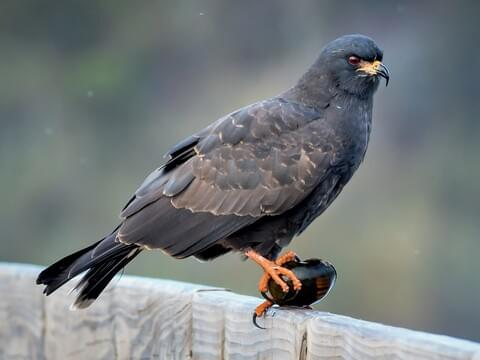

Densidad poblacional del Caracolero común (*Rostrhamus sociabilis*) en Florida.

datos tomados de:  

Ferguson, J. M., Reichert, B. E., Fletcher, R. J., & Jager, H. I. (2017). Detecting population–environmental interactions with mismatched time series data. *Ecology*, *98*(11), 2813–2822. http://www.jstor.org/stable/26602217

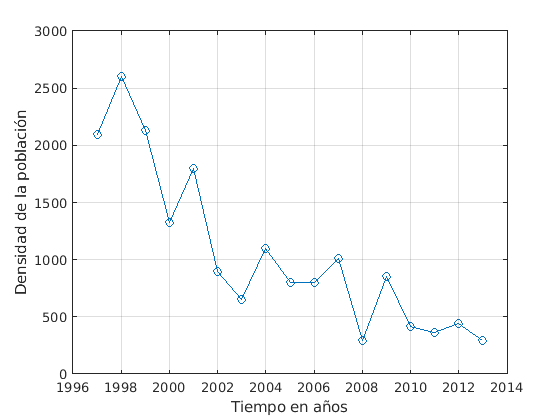

close all
%Lectura de los datos (tiempo en años y abundancia de la especie)
load("RealDataExamples/SNKIabundance.mat")
ydata = Abundance;
t = Year;
%graficos de los datos reales
plot(t, ydata, 'o-')
grid on
ylabel("Densidad de la población")
xlabel("Tiempo en años")

#### Mortalidad y natalidad como parámetros juntos

Estimación de condiciones iniciales y parámetros para la ecuación (1)

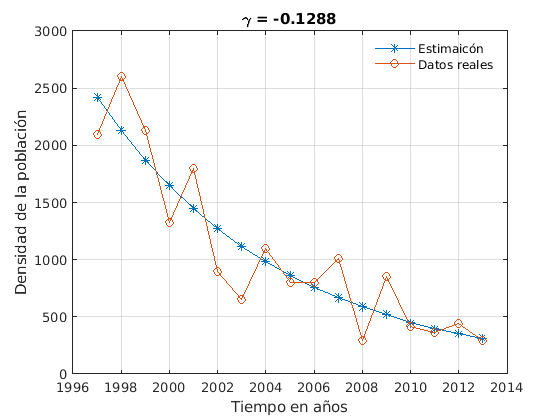

%Condiciones iniciales de estimación
%tetha0 = [condiciones_iniciales_ODE condicion_inicial_params]
theta0 = [1000, 0.5]';

%Limites inferiores y superiores en la estimación
% de condiciones iniciales y parámetros
lb = [0 -1];
ub = [4000 1];

%proceso de estimación de parámetros
opt = optimoptions('lsqcurvefit',"Display","off");
[theta] = lsqcurvefit(@ExponentialGrowthFun, theta0, t, ydata, lb, ub, opt);

%grafio datos reales vs ajuste
figure
plot(t, ExponentialGrowthFun(theta, t), '-*')
hold on
plot(t, ydata, '-o')
grid on
ylabel("Densidad de la población")
xlabel("Tiempo en años")
legend('Estimación', 'Datos reales', "Location","best","box", "off")
title("\gamma = " + num2str(theta(2)))

#### Con mortalidad y natalidad como parámetros separados

Estimación de condiciones iniciales y parámetros para la ecuación (3) con natalidad y mortalidad:

$\frac{dN(t)}{dt} = (\gamma -\mu)\, N(t)$         (3)

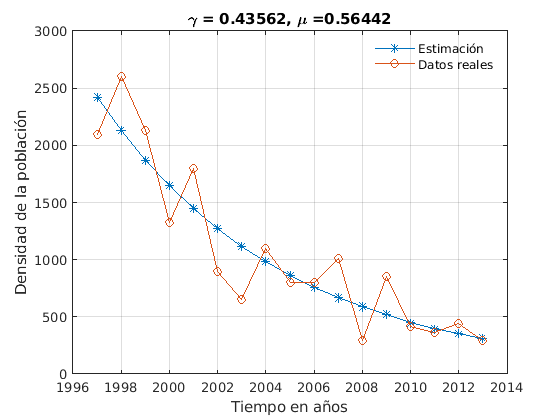

theta0 = [1000, 0.5, 0.5]';
lb = [0 0 0];
ub = [4000 1 1];

opt = optimoptions('lsqcurvefit',"Display","off");
[theta] = lsqcurvefit(@ExponentialGrowthDeadFun, theta0, t, ydata, lb, ub, opt);
figure
plot(t, ExponentialGrowthDeadFun(theta, t), '-*')
hold on
plot(t, ydata, '-o')
grid on
ylabel("Densidad de la población")
xlabel("Tiempo en años")
legend('Estimación', 'Datos reales', "Location","best","box", "off")
title("\gamma = " + num2str(theta(2)) + ", \mu ="+ num2str(theta(3)))

#### Estimación de población en 10 años

Pronóstico de densidad de individuos para los siguientes 10 años utilizando la ecuación (3) y los parámetros estimados

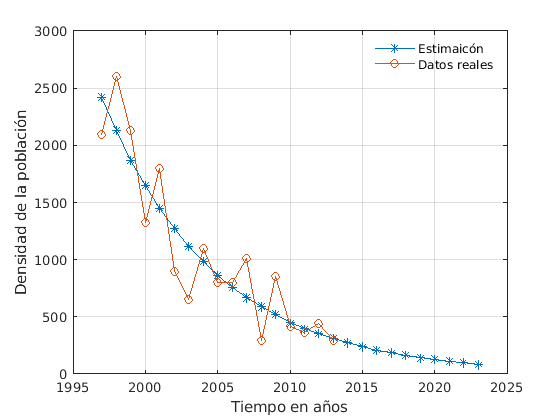

figure
newt = [t; t(end)+(1:10)']; 
plot(newt, ExponentialGrowthDeadFun(theta, newt), '-*')
hold on
plot(t, ydata, '-o')
grid on
ylabel("Densidad de la población")
xlabel("Tiempo en años")
legend('Estimación', 'Datos reales', "Location","best","box", "off")
hold on 

# Crecimiento Logístico con ejemplo real

#### La ecuación clásica: 


$$\frac{dN(t)}{dt} = \gamma\,N(t) \,\left( 1 - \frac{N(t)}{K}\right)$$



$$N(t) = \frac{KN_0}{N_0 + (K-P_0)exp(-\gamma t)}$$


con $\gamma$ la tasa de crecimiento y $K$la capacidad de carga del ambiente

#### Datos reales 

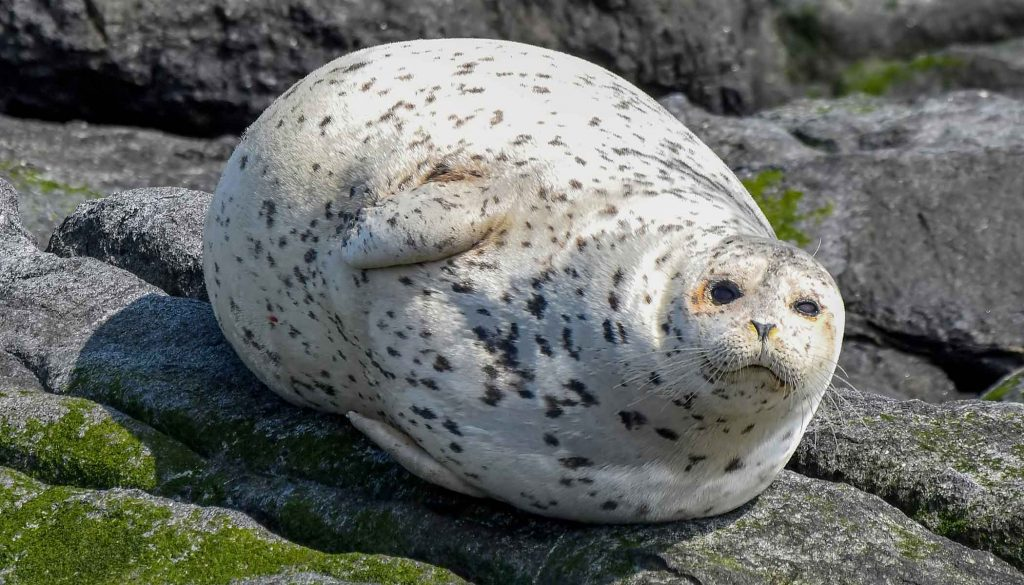

Densidad poblacional de la foca moteada (*Phoca vitulina*) en el mar de Frisia.

datos tomados de:  

[https://courses.lumenlearning.com/ivytech-collegealgebra/chapter/build-a-logistic-model-from-data/](https://courses.lumenlearning.com/ivytech-collegealgebra/chapter/build-a-logistic-model-from-data/)

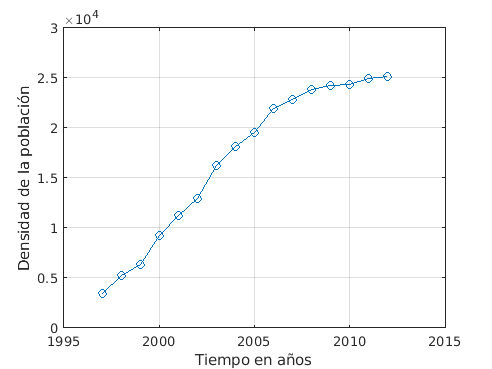

load("RealDataExamples/SealPopulation.mat")
ydata = Population;
t = Year;

figure
plot(t, ydata, 'o-')
grid on
ylabel("Densidad de la población")
xlabel("Tiempo en años")

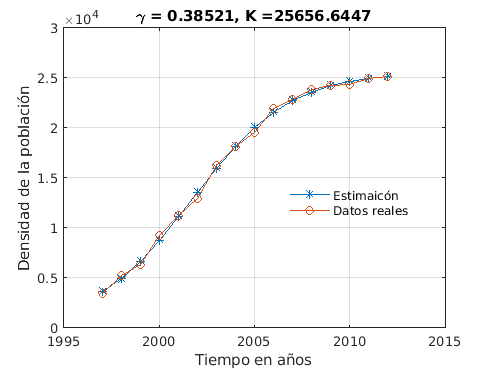

theta0 = [1000, 0.5, 0.5]';
lb = [0 0 0];
ub = [4000 1 100000];

opt = optimoptions('lsqcurvefit',"Display","off");
[theta] = lsqcurvefit(@LogisticGrowthFun, theta0, t, ydata, lb, ub, opt);
figure
plot(t, LogisticGrowthFun(theta, t), '-*')
hold on
plot(t, ydata, '-o')
grid on
ylabel("Densidad de la población")
xlabel("Tiempo en años")
legend('Estimación', 'Datos reales', "Location","best","box", "off")
title("\gamma = " + num2str(theta(2)) + ", K ="+ num2str(theta(3)))

#### Estimación de población en 15 años

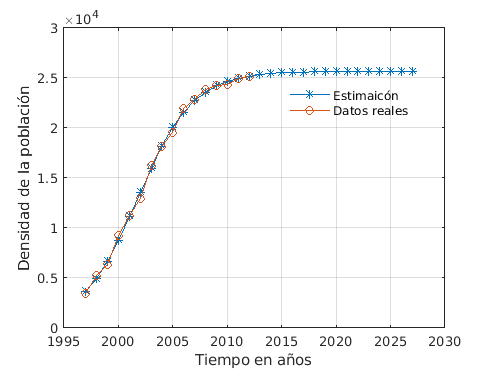

figure
newt = [t; t(end)+(1:15)']; 
plot(newt, LogisticGrowthFun(theta, newt), '-*')
hold on
plot(t, ydata, '-o')
grid on
ylabel("Densidad de la población")
xlabel("Tiempo en años")
legend('Estimación', 'Datos reales', "Location","best","box", "off")
hold on 

# Crecimiento con modelo de Ricker con ejemplo real

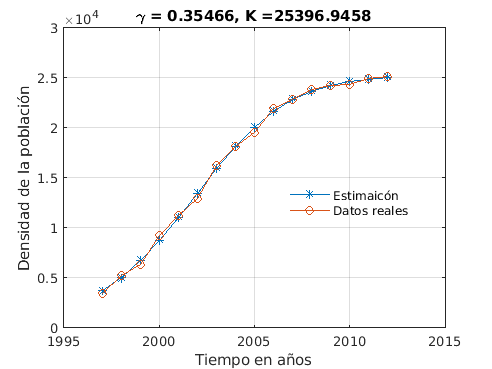

theta0 = [1000, 0.5, 1000]';
lb = [0 0 0];
ub = [4000 1 100000];

opt = optimoptions('lsqcurvefit',"Display","off");
[theta] = lsqcurvefit(@RickerGrowthFun, theta0, t, ydata, lb, ub, opt);
figure
plot(t, RickerGrowthFun(theta, t), '-*')
hold on
plot(t, ydata, '-o')
grid on
ylabel("Densidad de la población")
xlabel("Tiempo en años")
legend('Estimación', 'Datos reales', "Location","best","box", "off")
title("\gamma = " + num2str(theta(2)) + ", K ="+ num2str(theta(3)))

#### Estimación de población en 15 años con el modelo de Ricker

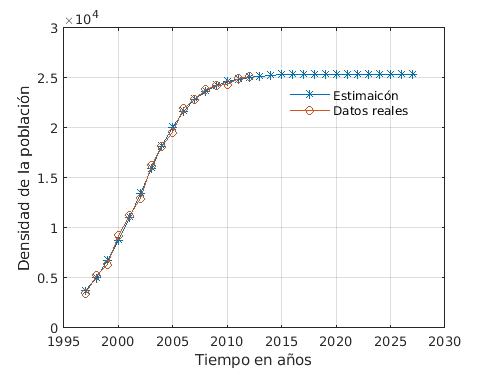

figure
newt = [t; t(end)+(1:15)']; 
plot(newt, RickerGrowthFun(theta, newt), '-*')
hold on
plot(t, ydata, '-o')
grid on
ylabel("Densidad de la población")
xlabel("Tiempo en años")
legend('Estimación', 'Datos reales', "Location","best","box", "off")
hold on 

# Crecimiento con Efecto Allee con datos reales

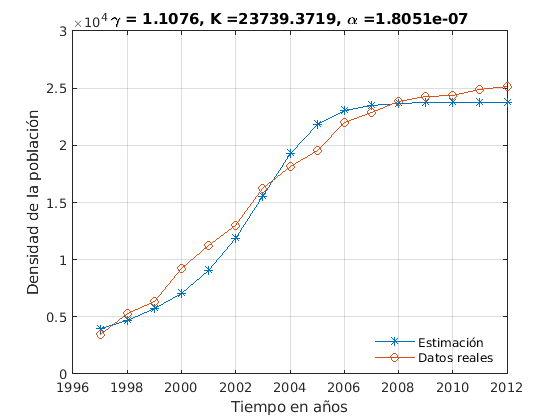

theta0 = [1000, 0.5, 1000, 200]';
lb = [0 0 0 0];
ub = [4000 2 100000 1000];

opt = optimoptions('lsqcurvefit',"Display","off");
[theta] = lsqcurvefit(@AlleeEfect, theta0, t, ydata, lb, ub, opt);
figure
plot(t, AlleeEfect(theta, t), '-*')
hold on
plot(t, ydata, '-o')
grid on
ylabel("Densidad de la población")
xlabel("Tiempo en años")
legend('Estimación', 'Datos reales', "Location","best","box", "off")
title("\gamma = " + num2str(theta(2)) + ", K ="+ num2str(theta(3)) + ", \alpha ="+ num2str(theta(4)))

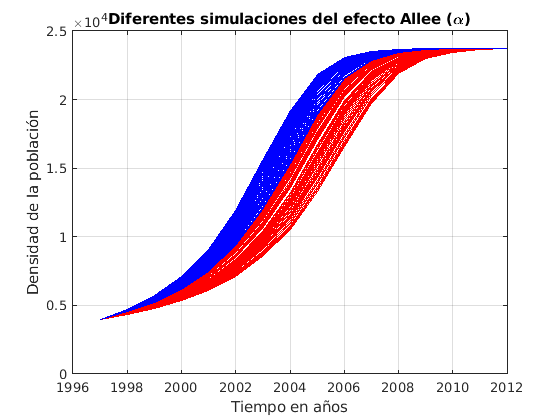

N = 100;
Y = [];

for i = 1 : N
    alpha = 1000 + (2000-1000) * rand(1,1);
    Y(i,:) = AlleeEfect([theta(1:3); alpha], t);
end

figure
plot(t, Y', '-r')
grid on
for i = 1 : N
    alpha = 0 + (1000-0) * rand(1,1);
    Y(i,:) = AlleeEfect([theta(1:3); alpha], t);
end
hold on
plot(t, Y', '-b')
title('Diferentes simulaciones del efecto Allee (\alpha)')
grid on
ylabel("Densidad de la población")
xlabel("Tiempo en años")
hold on

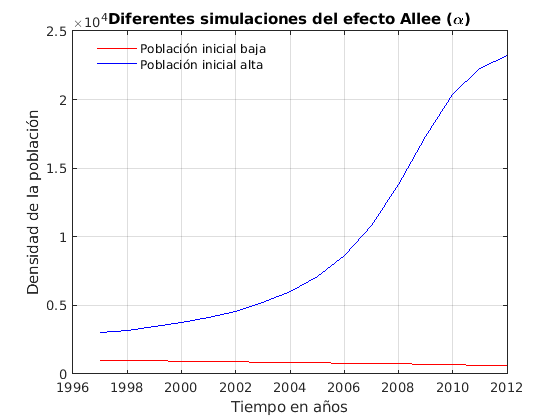

figure
plot(t, AlleeEfect([1000;theta(2:3); 1500], t) , '-r')
hold on
plot(t, AlleeEfect([3000;theta(2:3); 1500], t) , '-b')
title('Diferentes simulaciones del efecto Allee (\alpha)')
grid on
ylabel("Densidad de la población")
xlabel("Tiempo en años")
legend("Población inicial baja", "Población inicial alta", "Location","best","box","off")

# Ejemplo de matriz de Leslie con parámetros sintéticos

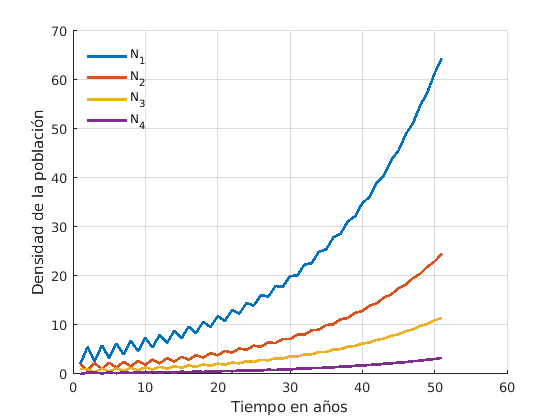

L = [0, 2.5, 0.5, 0.5;
    0.4, 0, 0, 0;
    0, 0.5, 0, 0;
    0,  0,  0.3, 0];

N0 = [2; 2; 1; 0];
N = [];
N(:,1) = N0;

for i = 1:50
    N(:, i+1) = L*N(:,i);
end

figure
for i = 1:4
    hold on
    plot(N(i,:),'LineWidth',2)
end
grid on
legend("N_1", "N_2", "N_3", "N_4",'Location','best','box','off')
ylabel("Densidad de la población")
xlabel("Tiempo en años")

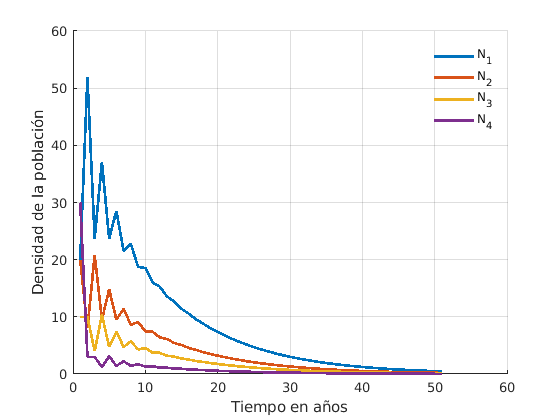

L = [0.1, 1.5, 0.5, 0.5;
    0.4, 0, 0, 0;
    0, 0.5, 0, 0;
    0,  0,  0.3, 0];

N0 = [20; 20; 10; 30];
N = [];
N(:,1) = N0;

for i = 1:50
    N(:, i+1) = L*N(:,i);
end

figure
for i = 1:4
    hold on
    plot(N(i,:),'LineWidth',2)
end
grid on
legend("N_1", "N_2", "N_3", "N_4",'Location','best','box','off')
ylabel("Densidad de la población")
xlabel("Tiempo en años")

# Ejemplo de procesos de saturación tipo Holling con parámetros sintéticos

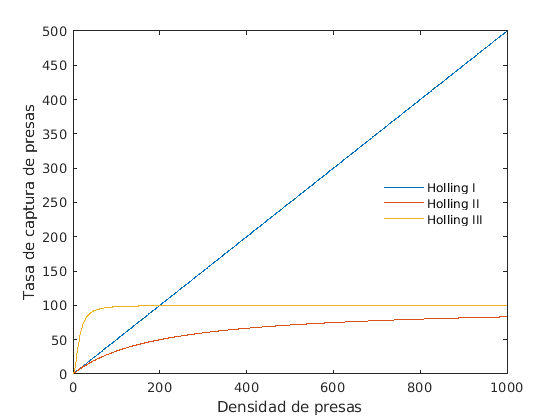

figure
N = 1:1000;
plot(HollingProcess(N, [1, 0.5]))
hold on
plot(HollingProcess(N, [2, 0.5, 0.01]))
plot(HollingProcess(N, [3, 0.5, 0.01, 2]))
legend("Holling I","Holling II","Holling III", 'Location','best', "box","off")
ylabel("Tasa de captura de presas")
xlabel("Densidad de presas")

#### Funciones complementarias utilizadas en el documento

function C = ExponentialGrowthDeadFun(theta, t)
%funcion exponencia con crecimiento y muerte
    IC = theta(1);
    [~, C] = ode45(@DifEq,t,IC);

    function dC = DifEq(~,State)
        dC = theta(2)*State - theta(3)*State;
    end
end


function C = ExponentialGrowthFun(theta, t)
%funcion exponencia con crecimiento
    IC = theta(1);
    [~, C] = ode45(@DifEq,t,IC);

    function dC = DifEq(~,State)
        dC = theta(2)*State;
    end
end


function C = LogisticGrowthFun(theta, t)
%funcion de crecimiento logistico clasico
    IC = theta(1);
    [~, C] = ode45(@DifEq,t,IC);

    function dC = DifEq(~,State)
        dC = theta(2)*State*(1-State/theta(3));
    end
end


function C = RickerGrowthFun(theta, t)
%funcion para el modelo de Ricker
    C(1) = theta(1);
    for i = 1:length(t)-1
        C(i+1) = C(i)*exp(theta(2)*(1-C(i)/theta(3)));
    end
    C = C';
end


function C = AlleeEfect(theta, t)
%funcion del efecto Allee
    IC = theta(1);
    [~, C] = ode45(@DifEq,t,IC);
    function dC = DifEq(~,State)
        dC = theta(2)*State*(1-State/theta(3))*((State-theta(4))/theta(3));
    end
end


function C = HollingProcess(N, theta)
    type = theta(1);
    alpha = theta(2);
    switch type
        case 1
            for i = 1:N
               C = alpha*N;
            end
        case 2
            h = theta(3);
            C = alpha.*N./(1+alpha*h.*N);
        case 3
            h = theta(3);
            n = theta(4);
            C = alpha.*N.^n./(1+alpha*h.*N.^n);
    end
end